# Laboratório de Controle - Aula 2 - 2021/1

## Ambiente de simulação do sistema digital de controle

## **Nome**: Yuri Rissi Negri

**Atividade 1: Análise da resposta do sistema digital de controle**

***Antes de fazer essa atividade, assista o video ***[***labca2***](https://youtu.be/cm9pgwOzeho)***.***

***Dúvidas sobre usar este live script para gerar o relatório: clique ***[aqui](https://youtu.be/KP5G5j7RRmM)***.***

Na figura 1 é mostrado o diagrama que será simulado. Um degrau de amplitude PWM é aplicado na entrada, o motor gira a uma certa velocidade (rpm), e o conversor A/D gera um valor inteiro correspondente a essa velocidade. Faça a simulação, observe a figura 2 e responda as perguntas.

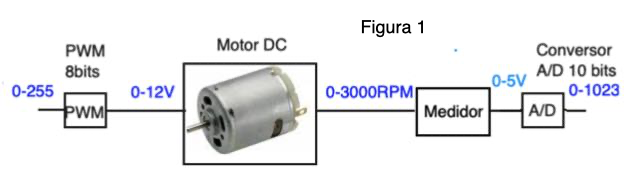

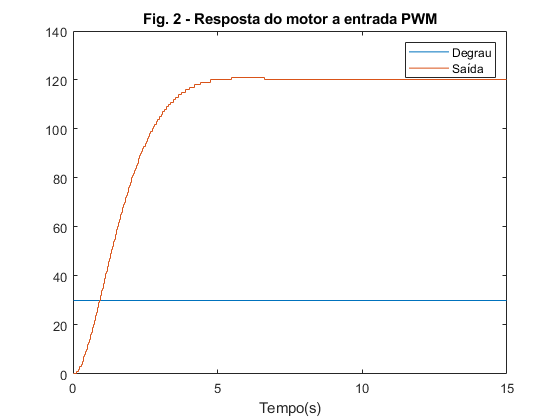

Ts=1e-3;
Tempo=15; 
arquivo='aula2_2018.slx';
[wn,PWM]=init(8,5);

out=sim(arquivo,Tempo);
u1=out.X(:,2);
y1=out.X(:,3);
t1=out.tout;

stairs(t1,[u1 y1]);legend('Degrau','Saída');xlabel('Tempo(s)');
title('Fig. 2 - Resposta do motor a entrada PWM');

1.1. Como obter o ganho desse sistema e qual esse ganho?

Resposta:

    O ganho é dado pela nosso valor na saída, dada pelo conversor A/D, sobre o nosso valor de entrada pela dada em PWM para esse nosso sistema. Assim, basta tomar no gráfico um ponto em regime permanente, obtendo um valor de Y = 120 e relacionar com nosso valor de Y= 30, que é nossa entrada em PWM. Portanto nosso ganho será dado por:

K = 120/30 = 4

1.2 Qual a constante de tempo desse sistema?

Resposta:

    Tomando o ponto onde obtemos aproximadamente 63% da nossa saída, temos que Y= 120 . 0,63 ~= 76. Portanto, tomando o ponto no gráfico em que Y= 76 vamos obter uma constante de tempo de 1,93 segundos.

1.3 Que tensão foi aplicada no motor (em volts) e qual foi a velocidade de regime correspondente em rpm?

Resposta:

    Utilizando uma regra de três para relacionar nossa entrada em PWM com os possíveis valores de tensão para o nosso sistema, podemos encontrar a tensão de entrada aplicada no motor:

 x  V  ------  30                               x = 1,41 V 

12 V  ------  255 

    Para nossa saída em RPM, podemos fazer de forma análoga, agora relacionando o conversor A/D com os possíveis valores de velocidade:

     x  RPM  ------  120                               x = 351,9 RPM

3000 RPM  ------  1023 

**Atividade 2 - Aproximação da resposta ao degrau por uma FT de primeira ordem + tempo morto**

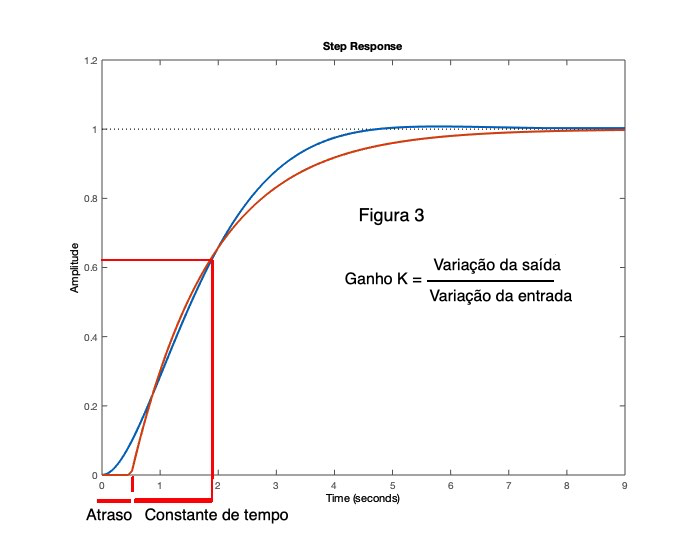

Na figura 3 mostra-se como aproximar uma resposta ao degrau (em azul) por uma FT de primeira ordem com tempo morto (em vermelho). Assume-se que haja um tempo morto inicial (embora não haja) e a constante de tempo é medida a partir dele. O script abaixo testa 10 valores de tempo morto e obtem os 10 modelos correspondentes, medindo a [norma euclidiana](https://pt.wikipedia.org/wiki/Norma_(matem%C3%A1tica)) do erro entre o modelo e a saída da resposta original ( $||erro||=||y_{original}-y_{modelo}||$).

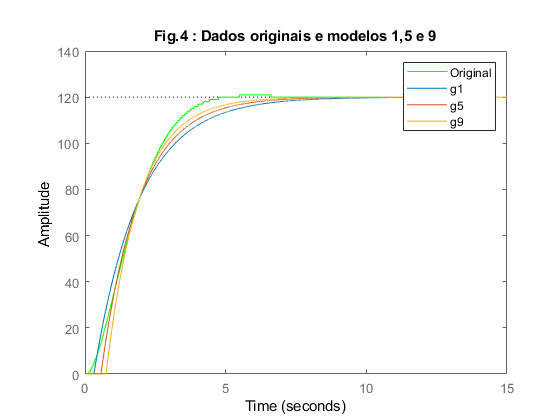

K=4; 
limiar=linspace(0.04,0.2,10);
for i=1:length(limiar)
    delay(i)=t1(sum(y1<limiar(i)*y1(end)));
    tau(i)=t1(sum(y1<0.63*y1(end)))-delay(i);
    g=tf(K,[tau(i) 1],'InputDelay', delay(i));
    ysim=step(PWM*g,t1);
    erro(i)=norm(y1-ysim);
end
plot(t1,y1,'g');hold on
for i=1:4:10
     g=tf(K,[tau(i) 1],'InputDelay', delay(i));
     step(PWM*g,t1);
end
title('Fig.4 : Dados originais e modelos 1,5 e 9');legend('Original','g1','g5','g9');
hold off

2.1 Comentar como cada modelo (g1,g5,g9) aproxima os valores no início da resposta, na constante de tempo e no valor em regime da saída original (em verde).

Resposta:

    Durante o inicio da resposta, podemos ver que a curva que mais se aproxima do nosso modelo original é dada por g1, pois é a que possui menor atraso, porém quando analisamos a constante de tempo, percebemos que as três curvas se interceptam e apresentam o mesmo valor quando o tempo atinge a constante de tempo do nosso modelo inicial (1,93 segundos). Quando analisamos o valor em regime, percebemos agora que a curva que mais se aproxima a curva original é a g9, uma vez que as outras demoram um tempo maior pra atingir o regime. Contudo, fazendo uma média e analisando essas três fases do gráfico em conjunto, podemos perceber que a curva que mais se aproxima da original e se mantem constante com um menor erro durante toda a faixa de tempo em relação as outras é a curva g5.

A figura 5a mostra o erro entre a saída original e a do modelo para os 10 atrasos utilizados no script. A Figura 5b mostra a constante de tempo $\tau$ para cada atraso.

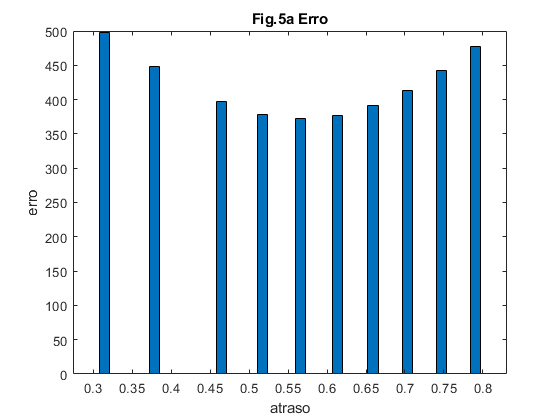

bar(delay,erro,0.3);xlabel('atraso');ylabel('erro');title('Fig.5a Erro');

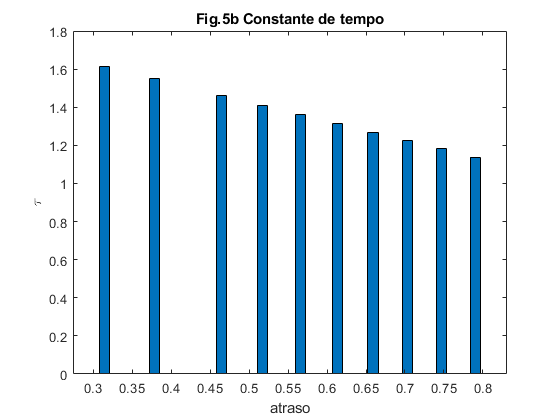

bar(delay,tau,0.3);xlabel('atraso');ylabel('\tau');title('Fig.5b Constante de tempo');

2.2 Explique o efeito do atraso escolhido sobre o erro e sobre a constante de tempo $\tau$, usando as figuras 4 e 5.

Resposta:

    Primeiramente analisando o gráfico da figura 4, podemos perceber que conforme variamos o atraso, o gráfico converge para uma faixa de valores central onde o erro é menor. Conforme aumentamos ou diminuímos o atraso em relação a esse valor central, temos um aumento no erro.

    Analisando o gráfico da figura 5, podemos perceber que conforme aumentamos o atraso, diminuímos a constante de tempo da nossa nova curva. Isso fica facíl de se perceber quando analisamos a figura 4, pelo fato de que, como visto anteriormente, todas as curvas passam pelo ponto da constante de tempo da curva original, de forma que a constante de tempo da nossa curva aproximada seja dada por:

$\tau$ = ( $\tau$original - atraso) 

2.3 Usando a figura 5, escolha o atraso e a constante de tempo $\tau$ para o modelo que dá o menor erro e substitua-os abaixo (tau e atraso), para comparar a saída desse modelo e a resposta original. Observando a figura 6, que partes da resposta no tempo ficam melhor aproximadas?

Dos gráficos, tiramos que: 

atraso = 0,55 segundos

$\tau$ = 1,35 segundos

    Analisando a figura 6, podemos perceber que as duas curvas mais se aproximam no periodo em torno do valor da constante de tempo.  

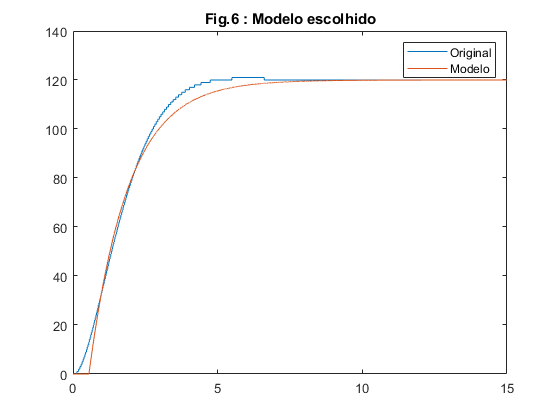

g=tf(K,[1.35 1],'InputDelay',0.55);
ysim=step(PWM*g,t1);
plot(t1,y1,t1,ysim);title('Fig.6 : Modelo escolhido');legend('Original','Modelo');

***IMPORTANTE: ao gerar a figura 6, mostre-a (compartilhando a tela) para o professor antes de avançar. Ela será usada para escolher os tempos de amostragem das atividades seguintes.***

**Atividade 3 - Simulação com diferentes tempos de amostragem Ts**

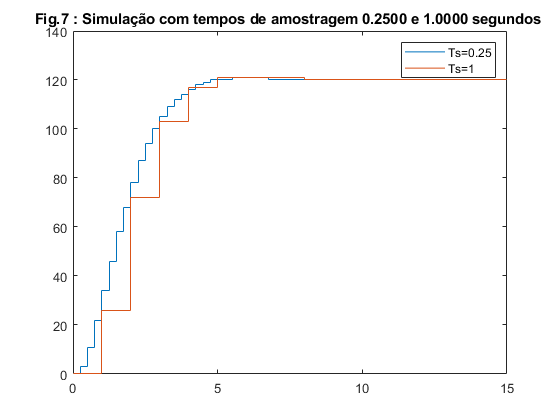

Ts1=0.25;
Ts=Ts1;
out=sim(arquivo,Tempo);
u2=out.X(:,2);
y2=out.X(:,3);
t2=out.tout;



Ts2=1;
Ts=Ts2;
out=sim(arquivo,Tempo);
u3=out.X(:,2);
y3=out.X(:,3);
t3=out.tout;

tit=sprintf('Fig.7 : Simulação com tempos de amostragem %0.4f e %0.4f segundos ',Ts1,Ts2);
stairs(t2,y2);hold on
stairs(t3,y3);title(tit);hold off; 
legend(strcat('Ts=',num2str(Ts1)), strcat('Ts=',num2str(Ts2)));

3.1 Em que instantes as curvas para os dois tempos de amostragem são iguais na Figura 7? Por quê?

Resposta:

    Analisando a figura 7, podemos perceber que as curvas se tocam a cada intervalo de 1 segundo, ou seja, nos pontos em que X = 1, X= 2, X= 3, etc. Isso ocorre pois definimos com Ts2 = 1, que é a metade da constante de tempo da nossa curva original. 

3.2 Explique o efeito do segurador de ordem zero nas curvas mostradas na figura 7, e informe em que blocos eles estão na figura 1 (abra o arquivo slx e confira).

Resposta:

  O segurador de ordem zero entá no bloco da planta discretizada, dentro do bloco de PWM. Ele tem a função de manter o sinal entre tempos de amostragem, o que pode ser observado no grafico, onde os valor do sinal mantem constante entre os valores selecionados para Ts1 e Ts2.

**Atividade 4 - Discretização do modelo de primeira ordem + tempo morto**

Caso tenha dúvidas sobre a discretização de um sistema de primeira ordem, veja o apêndice. Video mais conceitual sobre o tema pode ser visto em [Luis Aguirre](https://youtu.be/dJpidTfv8M8)

G=g


G =
 
                     4
  exp(-0.55*s) * ----------
                 1.35 s + 1
 
Continuous-time transfer function.



Gd=c2d(G,Ts2)


Gd =
 
           1.134 z + 0.9591
  z^(-1) * ----------------
              z - 0.4768
 
Sample time: 1 seconds
Discrete-time transfer function.



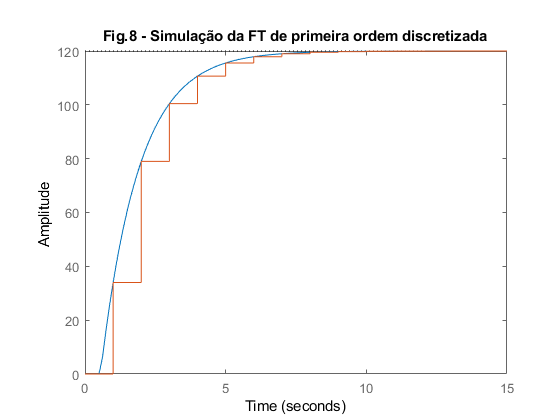

step(PWM*G,PWM*Gd, Tempo);title('Fig.8 - Simulação da FT de primeira ordem discretizada');

4.1 Explique o que é mostrado na figura 8 e que tempo de discretização foi utilizado

Resposta:

    Na figura 8 temos duas curvas, a azul é nosso sistema de primeira ordem na forma continua, ja em vermelho vamos ter a mesma curva discretizada, com um tempo de discretização igual a Ts2, que para o nosso caso será igual a 1 segundo 

4.2 Explique de onde vem o termo $z^{-d}$  de Gd e o explique o valor de $d$.

Resposta:  

   O termo $z^{-d}$ surge quando temos um atraso na nossa onda original. Assim quando fazemos a discretização de uma onda com atraso, vamos obter um termo na forma $z^{-d}$.

    O valor de d será dado pelo número de períodos de amostragem em que nossa curva se encontra em Y = 0, ou seja, o "tempo morto" que corresponde a d atrasos de tempo. Para o nosso caso, temos um atraso (0.55 segundos) menor que o nosso tempo de discretização Ts2 (1 segundo). Assim devido ao segurador de ordem zero, vamos ter Y = 0, até o próximo período de amostragem maior que o atraso, então teremos para o nosso caso que d = 1. Para exemplificar, podemos considerar um atraso de 1,1 segundos por exemplo, e como nosso período de amostragem se manteve em 1 segundo, serão necessários 2 tempos de amostragem o que significaria em um d = 2.

4.3 Quantos e quais são os [polos](https://www.mathworks.com/help/control/ref/lti.pole.html) de [malha fechada](https://www.mathworks.com/help/control/ug/using-feedback-to-close-feedback-loops.html) de Gd? Explique, lembrando que o sistema modelado tem ordem 1.

Resposta:

    Os pólos são definidos como as raízes do denominador de uma função de transferência, e o número de pólos é definido pela ordem do sistema. Assim observando Gd, fica fácil a análise de que teremos um pólo único em z = 0,4768.  

datetime('now')

ans = datetime
   25-Jun-2021 22:43:52


pwd

ans = 'C:\Users\asus1\Desktop\Faculdade\UFES\Materias\EAD\Lab de Controle\Aula2'

**Apêndice - discretização **